Fi = 1e3

Fi = 1000

Fs = 1e5

Fs = 100000

Tstop = 0.2

Tstop = 0.2000

mdl = "class_d"

mdl = "class_d"

simin = Simulink.SimulationInput(mdl)

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [0×0 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



simin = setModelParameter(simin, ...
    "StopTime", string(Tstop))

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [0×0 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''


input = strcat(mdl, "/Sine Wave")

input = "class_d/Sine Wave"

simin = setBlockParameter(simin, input, "Frequency", string(2*pi*Fi))

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×1 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



output = strcat(mdl, "/Sampled Output")

output = "class_d/Sampled Output"

simin = setBlockParameter(simin, output, "SampleTime", string(1/Fs))

simin =   SimulationInput with properties:

               ModelName: "class_d"
            InitialState: [0×0 Simulink.op.ModelOperatingPoint]
           ExternalInput: []
         ModelParameters: [1×1 Simulink.Simulation.ModelParameter]
         BlockParameters: [1×2 Simulink.Simulation.BlockParameter]
               Variables: [0×0 Simulink.Simulation.Variable]
               PreSimFcn: []
              PostSimFcn: []
              UserString: ''
    VariantConfiguration: ''



out = sim(simin)

### Building the rapid accelerator target for model: class_d
### Successfully built the rapid accelerator target for model: class_d


out =   Simulink.SimulationOutput:

                   tout: [20762229x1 double] 
               discrete: [20001x1 double] 
             continuous: [1x1 struct] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


timeseries = get(out, "continuous")

timeseries = struct with fields:
         time: [20762229×1 double]
      signals: [1×1 struct]
    blockName: 'class_d/Continuous Output'


sampled = get(out, "discrete")

sampled =          0
    1.1800
    2.6568
    4.6977
    5.6849
    7.6011
    9.1155
   10.2474
   12.1102
   13.1850


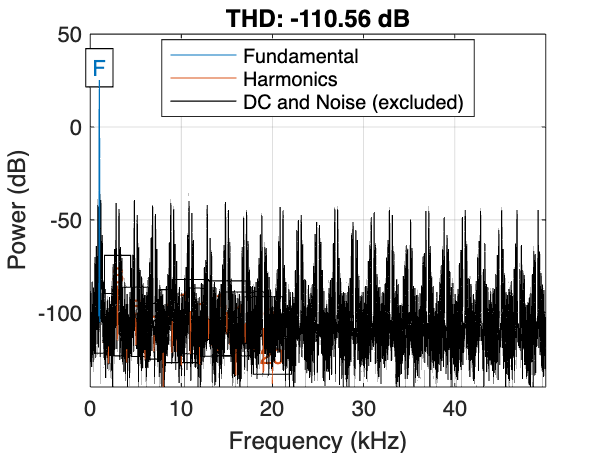

ans = -121.1406

thd(sampled,Fs,20)